# Resurging Disease Model

*Author:* Zachary del Rosario, Fall 2020

*Purpose:* Generate data with a known ground-truth for students to fit a model against, this time with a resurgance term.

## Generate Data

Generate data under a ground-truth setting.

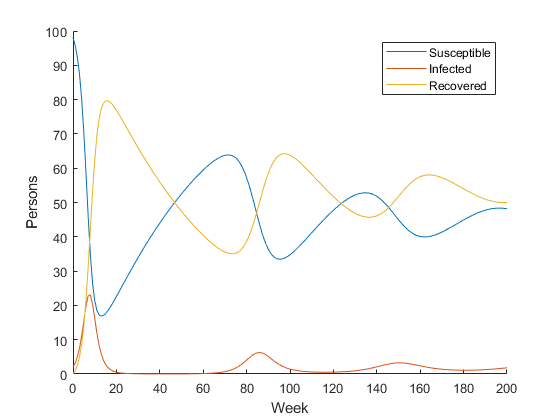

% Define parameters
beta = 1 / 90; % Infection rate (New / Susceptible / Infected / week)
gamma = 1 / 2; % Recovery rate (1 / week)
epsilon = 1 / 60; % Immunity decay rate (1 / week)
% Set up system
tab_state = fcn_make_table( ...
    "s", 98, ...
    "i", 2, ...
    "r", 0 ...
);
tab_system = fcn_make_table("beta", beta, "gamma", gamma, "epsilon", epsilon);

% Run simulation
tab_record = fcn_simulate(tab_state, tab_system, 200);

% Plot
figure(1); clf; hold on;
plot(tab_record.week, tab_record.s); label1 = "Susceptible";
plot(tab_record.week, tab_record.i); label2 = "Infected";
plot(tab_record.week, tab_record.r); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})

Check a summary of the simulation.

describe(tab_record)

ans = 6×5 table
      s          i          r        week       stat  
    ______    ________    ______    ______    ________

        98      23.076    79.676       200    "Max"   
    51.966      2.5125    58.024    150.25    "Q3"    
    45.863      2.2288    51.908       100    "Mean"  
    45.861      1.2065    52.458       100    "Median"
    39.986     0.51908    46.245     49.75    "Q1"    
    16.867    0.028989         0         0    "Min"   


We'll use this model as the ground-truth for a student exercise.

## Mask the Data

Mask the data on a detection threshold

% Set a lower detection threshold
min_i = 1;
wk1_min = 0; wk1_max = 20;
wk2_min = 60; wk2_max = 120;
% Filter the data based on thresholds
tab_tmp1 = tab_record( ...
    (tab_record.i >= min_i) & ...
    (tab_record.week >= wk1_min) & ...
    (tab_record.week <= wk1_max), ...
    :);
tab_wave1 = apply(@round, tab_tmp1)

tab_wave1 = 18×4 table
    s     i     r     week
    __    __    __    ____

    98     2     0      0 
    96     3     1      1 
    92     5     3      2 
    87     8     5      3 
    80    11     9      4 
    70    16    14      5 
    58    20    22      6 
    46    23    31      7 
    35    23    42      8 
    27    20    53      9 
    21    16    62     10 
    19    12    69     11 
    17     8    74     12 
    17     6    77     13 
    17     4    79     14 
    18     3    80     15 



tab_tmp2 = tab_record( ...
    (tab_record.i >= min_i) & ...
    (tab_record.week >= wk2_min) & ...
    (tab_record.week <= wk2_max), ...
    :);
tab_wave2 = apply(@round, tab_tmp2)

tab_wave2 = 32×4 table
    s     i    r     week
    __    _    __    ____

    64    1    35     72 
    64    1    35     73 
    63    1    35     74 
    63    2    35     75 
    62    2    36     76 
    61    3    36     77 
    60    3    37     78 
    59    4    38     79 
    57    4    39     80 
    55    5    40     81 
    53    5    42     82 
    51    6    44     83 
    48    6    46     84 
    46    6    48     85 
    44    6    50     86 
    41    6    52     87 


Write the data to a csv.

writetable(tab_wave1(tab_wave1.week <= 6, ["i", "week"]), "infected.csv")
writetable(tab_wave1(:, ["i", "week"]), "wave1.csv")
writetable(tab_wave2(:, ["i", "week"]), "wave2.csv")